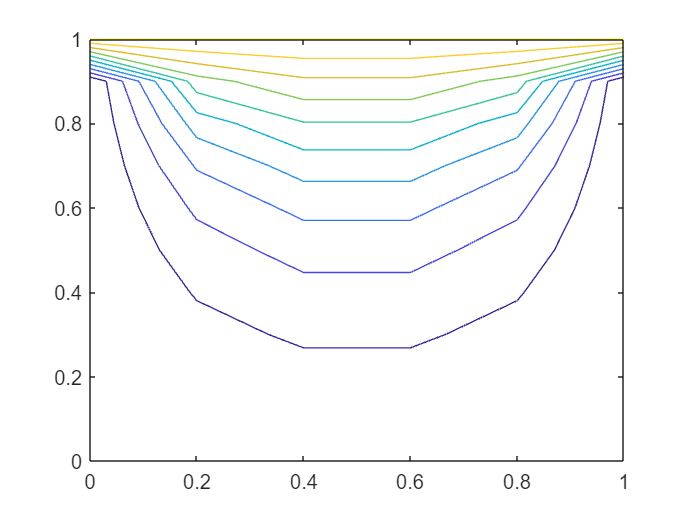

clc; clear;
[x, y] =  meshgrid(0:0.2:1, 0:0.1:1);

B = zeros(36,1);
for i = 9:9:36
    B(i) = -4;
end

A = zeros(36);
for i = 1:36
    A(i,i) = -10;
end

%for E1, E9, E28, E36
A(1, 2) = 4;
A(1, 10) = 1;

A(9, 18) = 1;
A(9, 8) = 4;

A(28, 19) = 1;
A(28, 29) = 4;

A(36, 27) = 1;
A(36, 35) = 4;

%for E2-E8
for i = 2:8
    A(i, i+9) = 1;
    A(i, i+1) = 4;
    A(i, i-1) = 4;
end

%for E29-E35
for i = 29:35
    A(i, i-9) = 1;
    A(i, i+1) = 4;
    A(i, i-1) = 4;
end

%for E10, E19
for i = [10 19]
    A(i, i+1) = 4;
    A(i, i-9) = 1;
    A(i, i+9) = 1;
end

%for E18, E27
for i = [18 27]
    A(i, i-1) = 4;
    A(i, i-9) = 1;
    A(i, i+9) = 1;
end

%for the rest (inner part)
for i = [11:17, 20:26]
    A(i, i-1) = 4;
    A(i, i+1) = 4;
    A(i, i-9) = 1;
    A(i, i+9) = 1;    
end

E = A\B;

Z = zeros(11, 6);
Z(11, :) = 1;
Z(2:10, 2) = E(1:9);

for i = 1:4
    Z(2:10, i+1) = E(9*i-8:9*i);
end

contour(x, y, Z)